# Ejemplo del cochecillo

Diseñamos el sistema dinámico del cochecito y lo simulamos para diferentes valores de la señal de control

Ecuaciones del sistema,


$$\dot x = v\cos(\psi)\\
\dot y = v\sin(\psi)\\
\dot \psi = \frac{v}{l}\tan(\phi)$$


$v = cte$ es la velocidad de avanze

$l$ es la batalla (distancia entre ejes)

$\phi$es el ángulo de las ruedas con el eje longitudinal del coche

Definimos valores iniciales y parámetros


v = 10.0; %v constante cochecillo
L = 1; %batalla
%u = @(t)0.1; %angulo de giro cte
u = @(t)0.1*sin(t)%variable en el tiempo

u = function_handle with value:
    @(t)0.1*sin(t)


tin = [0,10];
x0 =[0;0;0];%condición inicial

Empleamos ode45 para realizar la integración

añadimos la opción maxstep para suavizar la solución

opts = odeset('MaxStep',1e-1);
[t,x] = ode45(@(t,x)coche(t,x,u,v,L),tin,x0,opts);

Dibujamos la trayectoria

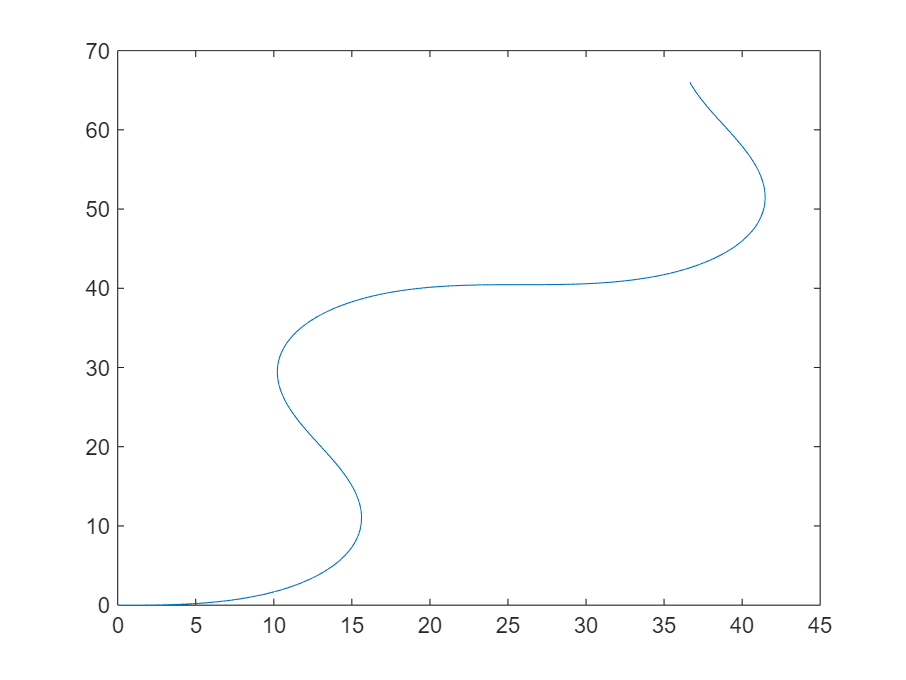

plot(x(:,1),x(:,2))

Ecuaciones del sistema

function xdot = coche(t,x,u,v,L)
xdot(1,1) = v*cos(x(3,1));
xdot(2,1) = v*sin(x(3,1));
xdot(3,1) = v/L*tan(u(t));
end
